**ISETHDR: A Physics-based Synthetic Radiance Dataset for High Dynamic Range Driving Scenes**

Zhenyi Liu, Devesh Shah, and Brian Wandell

**Figure 3: **Scene light groups. The dataset consists of 2000 scenes, each defined by four spectral radiance maps representing illumination by the sky, headlights, streetlights, and other light sources (e.g., tail lights, bicycle lights). To simulate various lighting conditions, the four maps are combined with different weights. For example, a daytime scene (left) has a bright sky and headlights, while a nighttime scene (right) has a darker sky with prominent headlights and streetlights. Using a lens model incorporating aperture and scratch effects (but excluding inter-reflections), scene radiance is converted to sensor irradiance. The graph on the right illustrates the illumination profile across a horizontal line. Note that headlight intensity remains constant between day and night, while reduced skylight lowers image contrast in darker areas. The software includes tools to select the weights to achieve desired dynamic range and low-light conditions.(lightGroupDynamicRangeSet.m).

ieInit

## Read light group scenes

imageID = '1112184733';
lgt = {'headlights','streetlights','otherlights','skymap'};
destPath = fullfile(isethdrsensorRootPath,'data',imageID);

scenes = cell(numel(lgt,1));
for ll = 1:numel(lgt)
    thisFile = sprintf('%s_%s.exr',imageID,lgt{ll});
    destFile = fullfile(destPath,thisFile);
    if ~exist(destFile,"file")
        ieWebGet('resourcetype','isethdrsensor',...
            'resource name',fullfile('data',imageID,thisFile),...
            'download dir',isethdrsensorRootPath);
    end
    scenes{ll} = piEXR2ISET(destFile);
end

*** Downloading data/1112184733/1112184733_headlights.exr from ISETHDRSensor SDR ... 
*** File is downloaded! 
*** Downloading data/1112184733/1112184733_streetlights.exr from ISETHDRSensor SDR ... 
*** File is downloaded! 
*** Downloading data/1112184733/1112184733_otherlights.exr from ISETHDRSensor SDR ... 
*** File is downloaded! 
*** Downloading data/1112184733/1112184733_skymap.exr from ISETHDRSensor SDR ... 
*** File is downloaded! 


## Create the optics and show the lightgroups

Denoised in: 17.709
Denoised in: 17.835
Denoised in: 17.748
Denoised in: 17.710


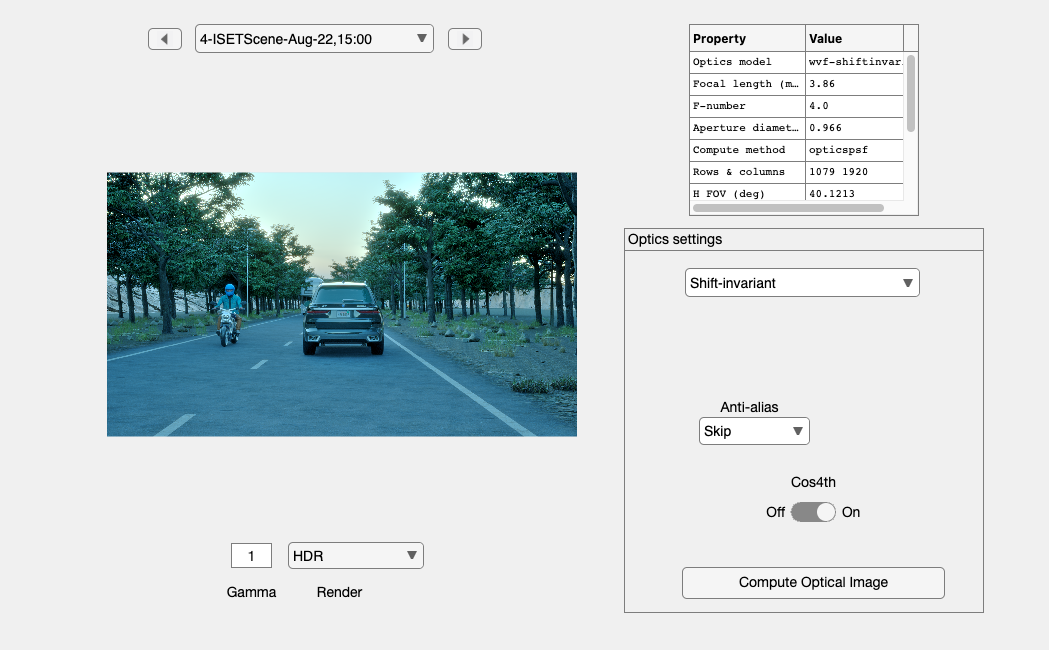

[oi,wvf] = oiCreate('wvf');
wvf = wvfSet(wvf, 'spatial samples',512);
[aperture, params] = wvfAperture(wvf,'nsides',5,...
    'dot mean',50, 'dot sd',20, 'dot opacity',0.5,'dot radius',5,...
    'line mean',50, 'line sd', 20, 'line opacity',0.5,'linewidth',2);

% Show the light group OIs.  This takes a while to denoise.  Not
% needed for the rest of the code to run.
ois = cell(4,1);
for ii=1:numel(scenes)
    ois{ii} = oiCompute(oi,scenes{ii},'crop',true);
    ois{ii} = piAIdenoise(ois{ii});
    oiWindow(ois{ii},'render flag','hdr');
    drawnow;
end

## Day scene

% It is possible to set the dynamic range and get light group weights
% this way
%
%  DR = 1e3;
%  [scene, wgts] = lightGroupDynamicRangeSet(scenes, DR);

wgts_day = [0.5019    0.0063    0.0083    100];
scene = sceneAdd(scenes, wgts_day);
dayScene = piAIdenoise(scene);

Denoised in: 17.775



% sceneWindow(thisScene,'gamma',0.3);

## Blur and flare

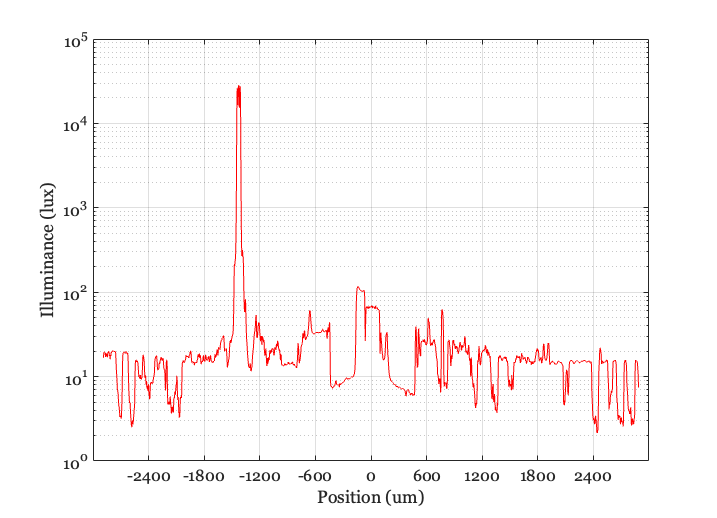

oiDay = oiCompute(oi, dayScene,'aperture',aperture,'crop',true,'pixel size',3e-6);

% oi1 = oiAdjustIlluminance(oi1, 5e4, 'max');
udata1 = oiPlot(oiDay,'illuminance hline',[1, 595]);
set(gca,'yscale','log');

## Create ip and sensor from the oi

[ipDay,sensorDay] = piRadiance2RGB(oiDay, 'etime', 1/200,'analoggain',1);

eT: 5.000000 ms 


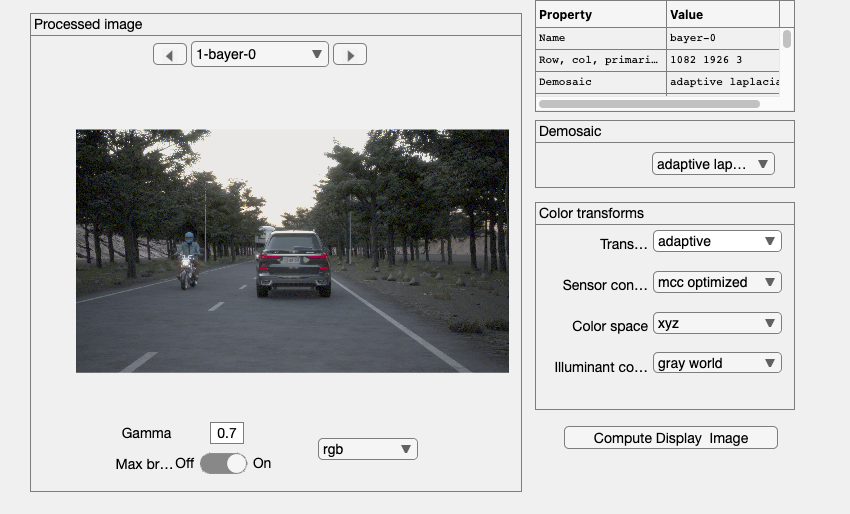

%{
 % Equivalent
 ip = ipCreate;
 ip = ipCompute(ip,sensorDay,'hdr white',true);
 ipWindow(ip,'gamma',0.7);
%}

ipWindow(ipDay,'gamma',0.7);


%{
srgb = ipGet(ip, 'srgb');
imwrite(srgb,'~/Desktop/day.png');
%}

## Night

wgts_night = [0.5019    0.0063    0.0083    5e-5];
scene = sceneAdd(scenes, wgts_night);
nightScene = piAIdenoise(scene);

Denoised in: 18.610



% sceneWindow(thisScene,'renderflag','hdr');

## Create the OI

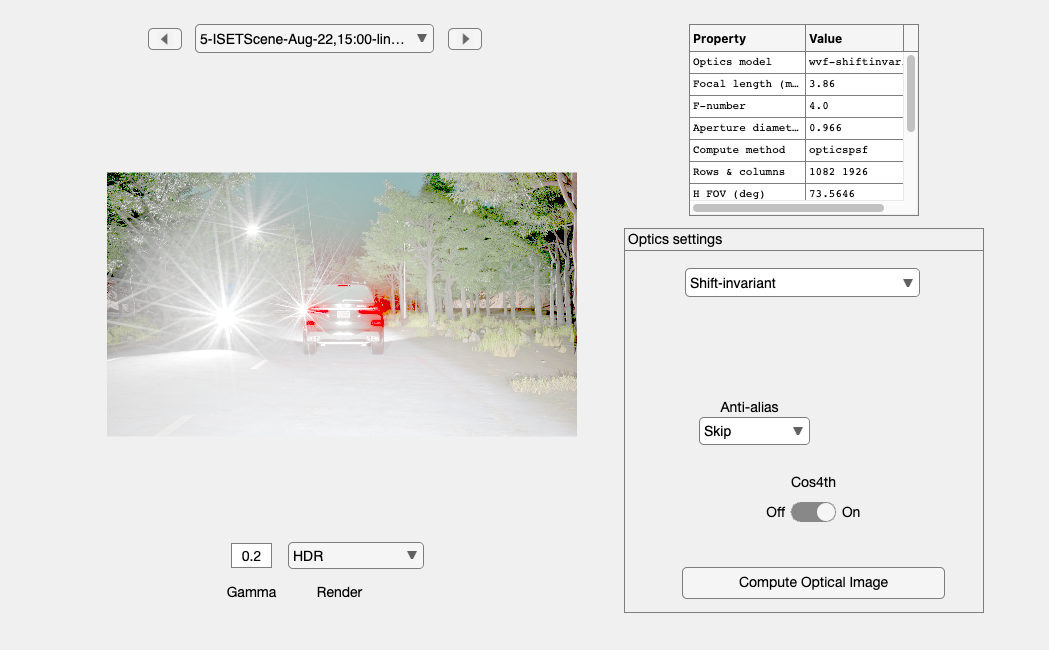

oiNight = oiCompute(oi, nightScene,'aperture',aperture,'crop',true,'pixel size',3e-6);
oiNight = oiAdjustIlluminance(oiNight, 5e4, 'max');
oiWindow(oiNight,'gamma',0.2);

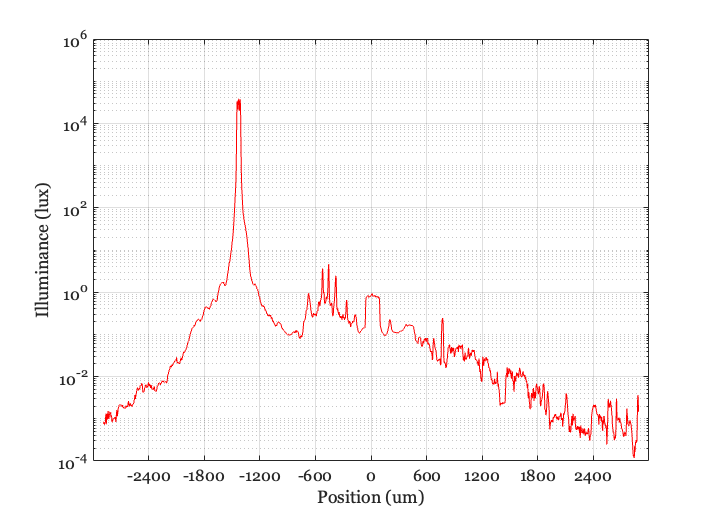


% Plot the log luminance through the bright headlight
[udata2, g] = oiPlot(oiNight,'illuminance hline',[1, 595]);
set(gca,'yscale','log');

## Make an IP directly from the oi. Goes through

[ipNight, sensorNight] = piRadiance2RGB(oiNight, 'etime', 1/10,'analoggain',1);

eT: 100.000000 ms 


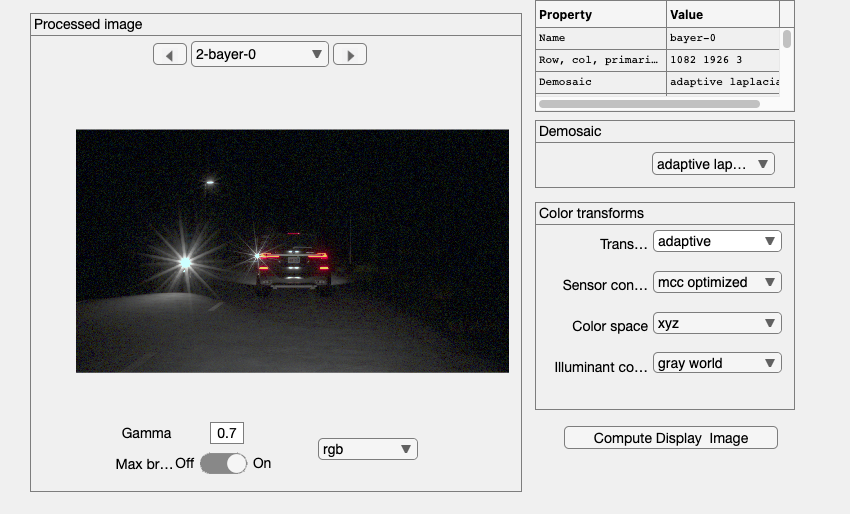

% sensorWindow(sensorNight);

ipWindow(ipNight,'gamma',0.7);


%{
srgb = ipGet(ipNight, 'srgb');
imwrite(srgb,'~/Desktop/night.png');
%}

## Compare the oiDay and oiNight illuminance

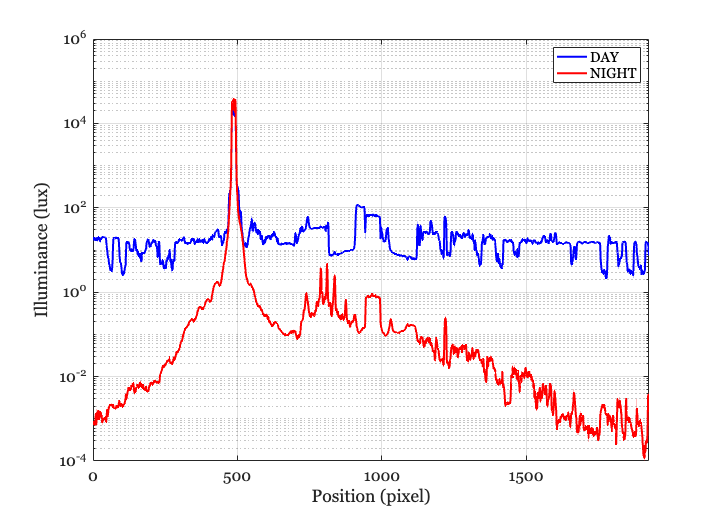

nPoints = numel(udata1.data);
% Notice that the headlight is the same in the two cases.
ieNewGraphWin;
plot(1:nPoints,udata1.data, 'b', 'LineWidth', 2); hold on 
plot(1:nPoints,udata2.data, 'r', 'LineWidth', 2);

set(gca, 'YScale', 'log');
legend('DAY', 'NIGHT', 'FontSize', 14);
xlabel('Position (pixel)', 'FontSize', 16);
ylabel('Illuminance (lux)', 'FontSize', 16);

% Set the font size for the axes
set(gca, 'FontSize', 16);
grid on
xlim([0,nPoints]);